# HGF Toolbox Demo

## Load binary input

First, we will load the example binary inputs $u$ provided in the file example_binary_input.txt:

u = load('example_binary_input.txt');

The inputs are simply a time series of 320 0s and 1s. This is the input sequence used in the task of Iglesias et al. (2013), *Neuron*, **80**(2), 519-530.

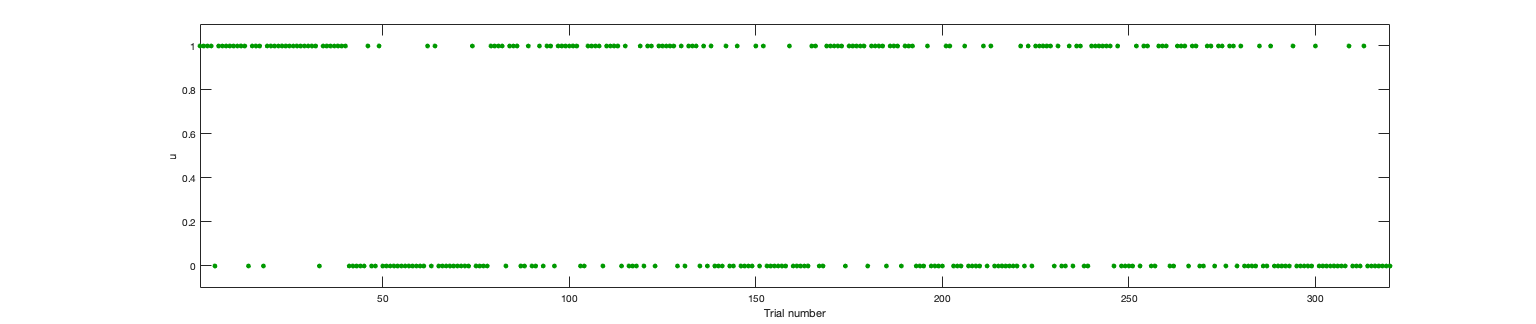

scrsz = get(0,'ScreenSize');
outerpos = [0.2*scrsz(3),0.7*scrsz(4),0.8*scrsz(3),0.3*scrsz(4)];
figure('OuterPosition', outerpos)
plot(u, '.', 'Color', [0 0.6 0], 'MarkerSize', 11)
xlabel('Trial number')
ylabel('u')
axis([1, 320, -0.1, 1.1])

## Find Bayes optimal parameter values

Now let's use the fitModel function to find the 'Bayes optimal' perceptual parameters for this dataset under the binary HGF model. By Bayes optimal we mean the particular parameter values that produce the least cumulative Shannon surprise for a given input sequence $u$. This means that an agent using this parameter setting would experience the least possible surprise when exposed to the given inputs under the given perceptual model.

The point of estimating the optimal parameter values is that we can use them as prior means when fitting observed responses. If the agents whose response we're observing are reasonably well able to perform their task, we may assume that their parameter values are distributed around the optimal values.

We provide fitModel with four arguments.

- The first argument, which would normally be the observed responses, is empty (ie, []) here because the optimal parameter values are independent of any responses.

- The second argument is the inputs *u.*

- The third argument is the perceptual model, *hgf_binary* here. We need to use the prefix 'tapas_' and the suffix '_config' in order to find the correct configuration file

- The fourth argument is the response model, *bayes_optimal_binary* here. Again we need to use the same prefix and suffix. In fact, bayes_optimal_binary is a kind of pseudo-response model because instead of providing response probabilities it simply calculates the Shannon surprise elicited by each new input given the current perceptual state.

- The fifth argument is the optimization algorithm to be used, *quasinewton_optim* here, which is a variant of the Broyden-Fletcher-Goldfarb-Shanno (BFGS) algorithm.

bopars = tapas_fitModel([],...
                         u,...
                         'tapas_hgf_binary_config',...
                         'tapas_bayes_optimal_binary_config',...
                         'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 1]
      om: [NaN -3.4295 -6.0087]

Model quality:
    LME (more is better): -206.2869
    AIC (less is better): 411.9067
    BIC (less is better): 419.4433
 
    AIC and BIC are approximations to -2*LME = 412.5739.
 


The only parameter whose Bayes optimal values we've estimated is $\omega$. This is the tonic volatility in the HGF. At the first level, $\omega_1$ is undefined (NaN) because in the binary HGF the first level is discrete, not continuous. At the second level, we find an optimal value of, for example, $\omega_2=-3.43$, and at the third level one of, for example, $\omega_3=-6.01$ (this will vary on different runs of this script).

The other parameters are fixed to a particular value because their prior variance has been set to zero in the configuration file *tapas_hgf_binary_config.m. *This means that their posterior means, displayed here, are the same as the prior means set in *tapas_hgf_binary_config.m*.

Their meanings are

- $\mu_0$ and $\sigma_0$ are the initial values of the perceptual state

- $\rho$ is a drift parameter, fixed to zero (ie, no drift) in this example

- $\kappa$ is a parameter that describes the couple between the different levels of the HGF, fixed to 1 in this example

For model comparison purposes, several measures of model quality are given by fitModel. The most important of these is the log-model evidence (LME).

## Simulate responses

Next, we simulate an agent's responses using the simModel function. To do that, we simply choose values for $\omega$. Here, we take $\omega_2=-2.5$ and $\omega_3=-6$. But in addition to the perceptual model *hgf_binary*, we now need a response model. Here, we take the unit square sigmoid model, *unitsq_sgm*, with parameter $\zeta=5$. The last argument is an optional seed for the random number generator.

sim = tapas_simModel(u,...
                     'tapas_hgf_binary',...
                     [NaN 0 1 NaN 1 1 NaN 0 0 1 1 NaN -2.5 -6],...
                     'tapas_unitsq_sgm',...
                     5,...
                     12345);

Ignored trials: none


The general meaning of the arguments supplied to simModel is explained in the manual and in the file *tapas_simModel.m*. The specific meaning of each argument in this example is explained in the configuration files of the perceptual model (*tapas_hgf_binary_config.m*) and of the response model (*tapas_unitsq_sgm_config.m*).

## Plot simulated responses

We can plot our simulated responses $y$ using the plotting function for *hgf_binary* models.

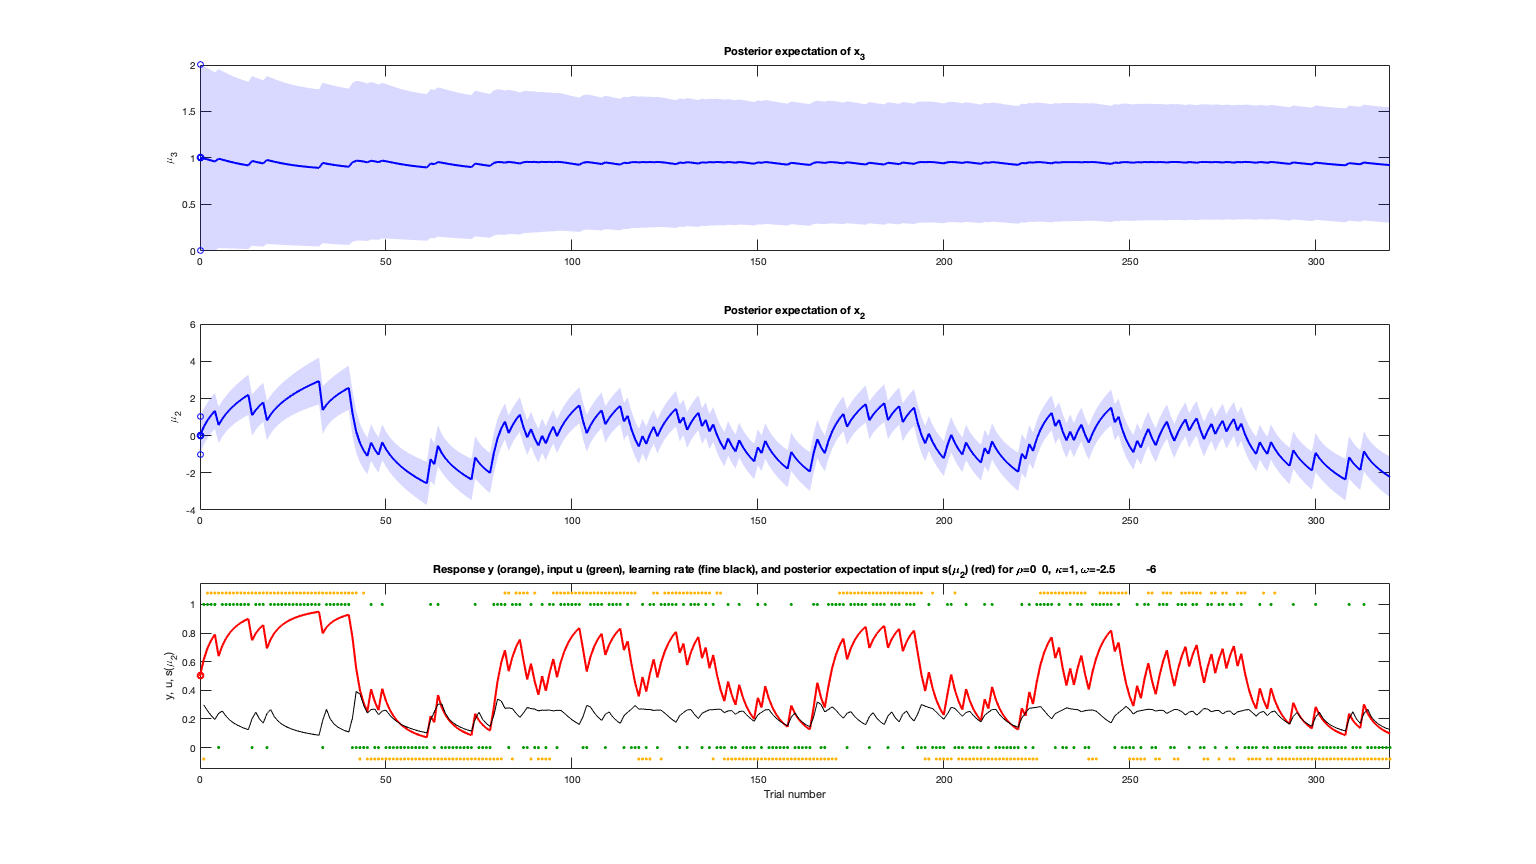

tapas_hgf_binary_plotTraj(sim)

## Recover parameter values from simulated responses

We can now try to recover the parameters we put into the simulation ($\omega_2=-2.5$ and $\omega_3=-6$) using fitModel.

est = tapas_fitModel(sim.y,...
                     sim.u,...
                     'tapas_hgf_binary_config',...
                     'tapas_unitsq_sgm_config',...
                     'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [NaN 0 1]
    sa_0: [NaN 0.1000 1]
     rho: [NaN 0 0]
      ka: [1 1]
      om: [NaN -2.3893 -4.5534]

 
Parameter estimates for the observation model:
    ze: 5.8761

Model quality:
    LME (more is better): -55.0381
    AIC (less is better): 102.2134
    BIC (less is better): 113.5184
 
    AIC and BIC are approximations to -2*LME = 110.0763.
 


We find, for example, $\omega_2=-2.53$ and, for example $\omega_3=-6.03$ (this will vary on different runs of this script). How good is that? It doesn't look bad, but the answer is that we cannot say anything from doing this just once. We have to repeat the simulation/estimation procedure many times and then look at the distribution of estimated $\omega$ values. This has been done in Mathys et al. (2014), *Frontiers in Human Neuroscience,* **8**:825, where we found that for moderate and low noise, parameter values can be recovered with good precision in the range observed for human subjects in Iglesias et al. (2013), *Neuron*, **80**(2), 519-530.

## Check parameter identifiability

To check how well the parameters could be identified, we can take a look at their posterior correlation. This gives us an idea to what degree changing one parameter value can be compensated by changing another. Of course changing a parameter is fully equivalent to changing that same parameter, therefore the values on the diagonal of the correlation matrix are all 1. However, it would be worrisome if changing one parameter's value were equivalent to changing another in the same direction (correlation +1) or in the opposite direction (correlation -1). In these cases the two parameters cannot be identified independently and one of them needs to be fixed. The other parameter can then be estimated conditional on the value of the one that has been fixed.

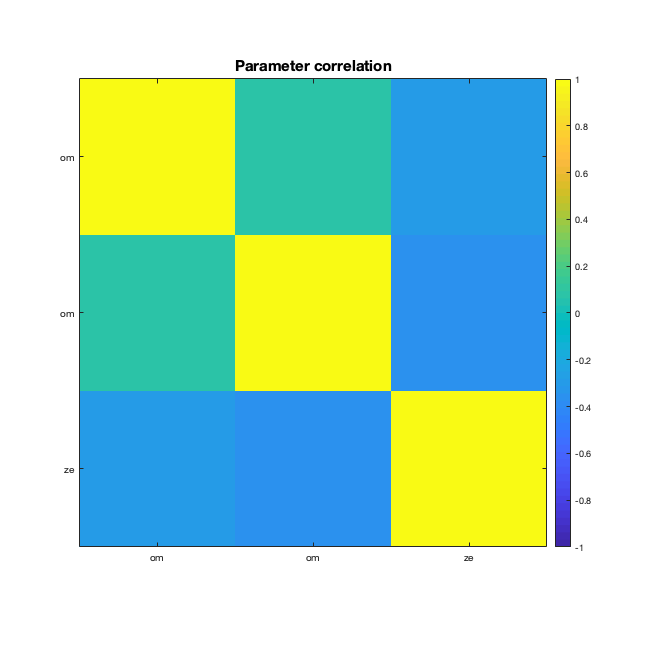

tapas_fit_plotCorr(est)

In this case, there is nothing to worry about. Unless their correlation is very close to +1 or -1, two parameters are identifiable, meaning that they describe distinct aspects of the data.

The posterior parameter correlation matrix is stored in est.optim.Corr,

disp(est.optim.Corr)

    1.0000    0.0877   -0.2866
    0.0877    1.0000   -0.3600
   -0.2866   -0.3600    1.0000



while the posterior parameter covariance matrix is stored in est.optim.Sigma

disp(est.optim.Sigma)

    0.0253    0.1193   -0.0057
    0.1193   73.0883   -0.3878
   -0.0057   -0.3878    0.0159



## Posterior means

The posterior means of the estimated as well as the fixed parameters can be found in est.p_prc for the perceptual model and in est.p_obs for the observation model:

disp(est.p_prc)

      mu_0: [NaN 0 1]
      sa_0: [NaN 0.1000 1]
       rho: [NaN 0 0]
        ka: [1 1]
        om: [NaN -2.3893 -4.5534]
         p: [NaN 0 1 NaN 0.1000 1 NaN 0 0 1 1 NaN -2.3893 -4.5534]
    ptrans: [NaN 0 1 NaN -2.3026 0 NaN 0 0 0 0 NaN -2.3893 -4.5534]



disp(est.p_obs)

        ze: 5.8761
         p: 5.8761
    ptrans: 1.7709



The posterior means are contained in these structures separately by name (e.g., om for $\omega$) as well as jointly as a vector $p$ in their native space and as a vector $p_{\mathrm{trans}}$ in their transformed space (ie, the space they are estimated in). For details, see the manual.

## Inferred belief trajectories

As with the simulated trajectories, we can plot the inferred belief trajectories implied by the estimated parameters.

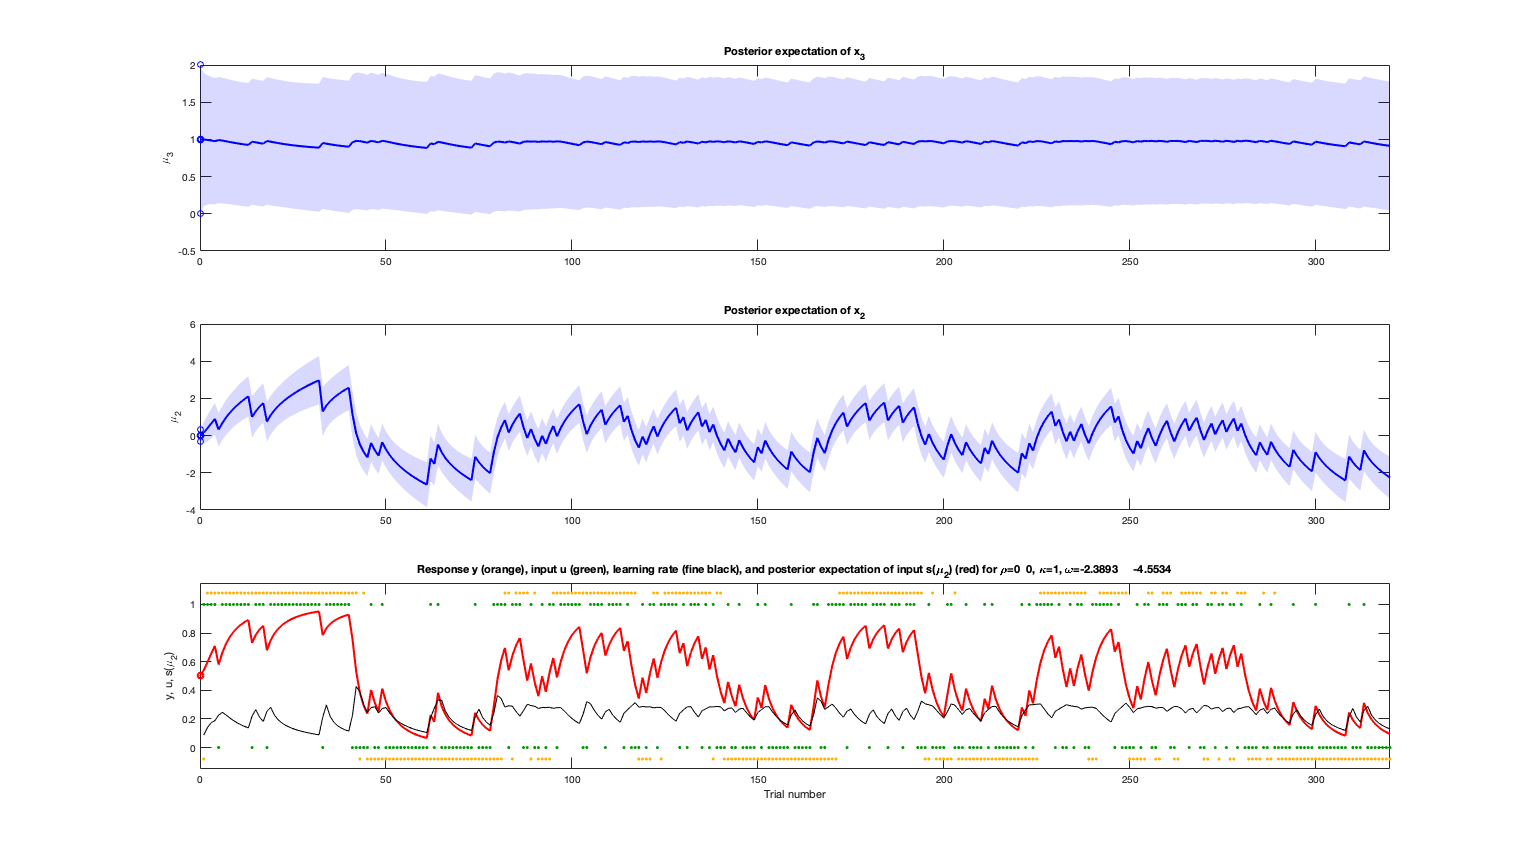

tapas_hgf_binary_plotTraj(est)

These trajectories can be found in est.traj:

disp(est.traj)

       mu: [320×3 double]
       sa: [320×3 double]
    muhat: [320×3 double]
    sahat: [320×3 double]
        v: [320×3 double]
        w: [320×2 double]
       da: [320×3 double]
       ud: [320×3 double]
      psi: [320×3 double]
     epsi: [320×3 double]
       wt: [320×3 double]



## Changing the perceptual model

Next, let's try to fit the same data using a different perceptual model while keeping the same response model. We will take the Rescorla-Wagner model *rw_binary*.

est1a = tapas_fitModel(sim.y,...
                       sim.u,...
                       'tapas_rw_binary_config',...
                       'tapas_unitsq_sgm_config',...
                       'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    v_0: 0.5000
     al: 0.2393

 
Parameter estimates for the observation model:
    ze: 5.7729

Model quality:
    LME (more is better): -53.7119
    AIC (less is better): 97.2329
    BIC (less is better): 104.7695
 
    AIC and BIC are approximations to -2*LME = 107.4238.
 


The single estimated perceptual parameter is the constant learning rate $\alpha$.

Just as for *hgf_binary*, we can plot posterior correlations and inferred trajectories for *rw_binary*.

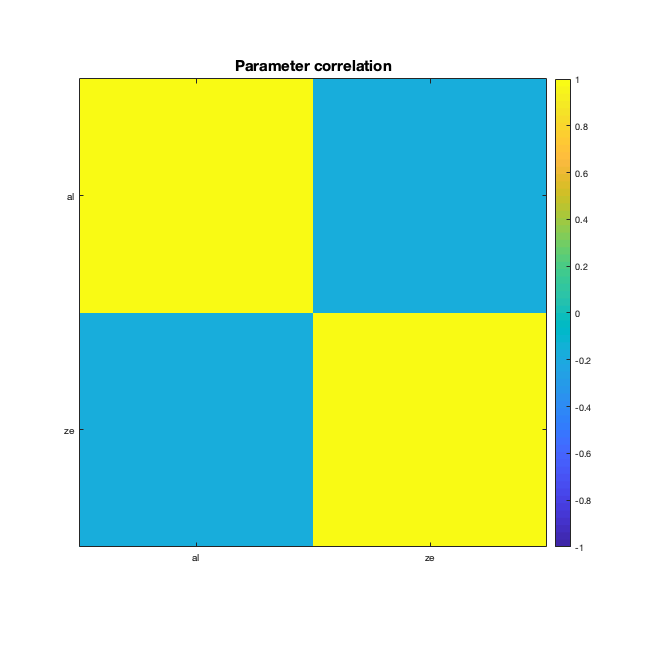

tapas_fit_plotCorr(est1a)

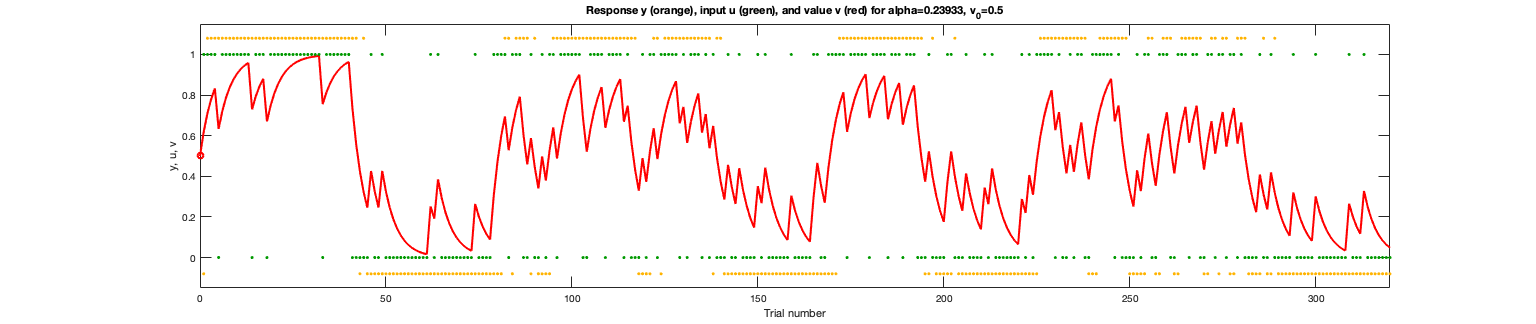

tapas_rw_binary_plotTraj(est1a)

## Input on a continuous scale

Up to now, we've only used binary input - 0 or 1. However, many of the most interesting time series are on a continuous scale. As an example, we'll use the exchange rate of the US Dollar to the Swiss Franc during much of 2010 and 2011.

usdchf = load('example_usdchf.txt');

As before, we'll first estimate the Bayes optimal parameter values. This time, we'll take a 2-level HGF for continuous-scaled inputs.

bopars2 = tapas_fitModel([],...
                         usdchf,...
                         'tapas_hgf_config',...
                         'tapas_bayes_optimal_config',...
                         'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [1.0315 1]
    sa_0: [3.2889e-05 0.0697]
     rho: [0 0]
      ka: 1
      om: [-11.8557 -5.9085]
    pi_u: 9.3870e+06

Model quality:
    LME (more is better): 2376.7071
    AIC (less is better): -4763.2439
    BIC (less is better): -4736.7239
 
    AIC and BIC are approximations to -2*LME = -4753.4142.
 


And again, let's check the posterior correlation and the trajectories:

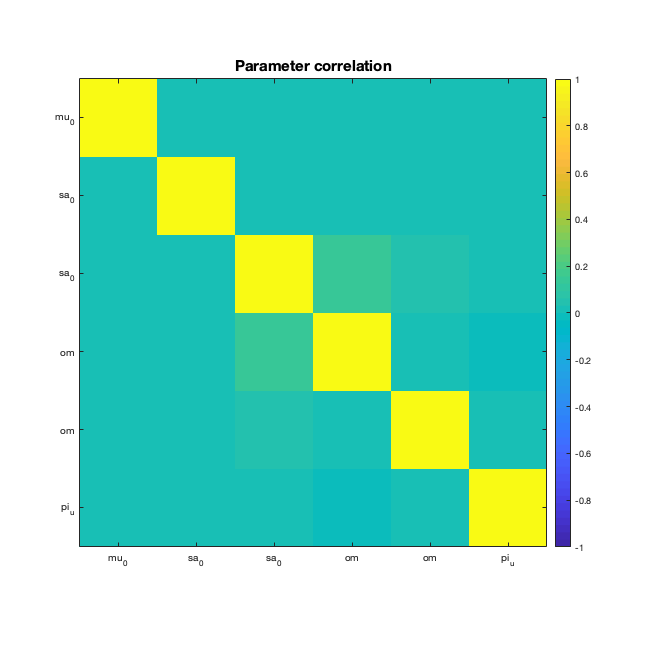

tapas_fit_plotCorr(bopars2)

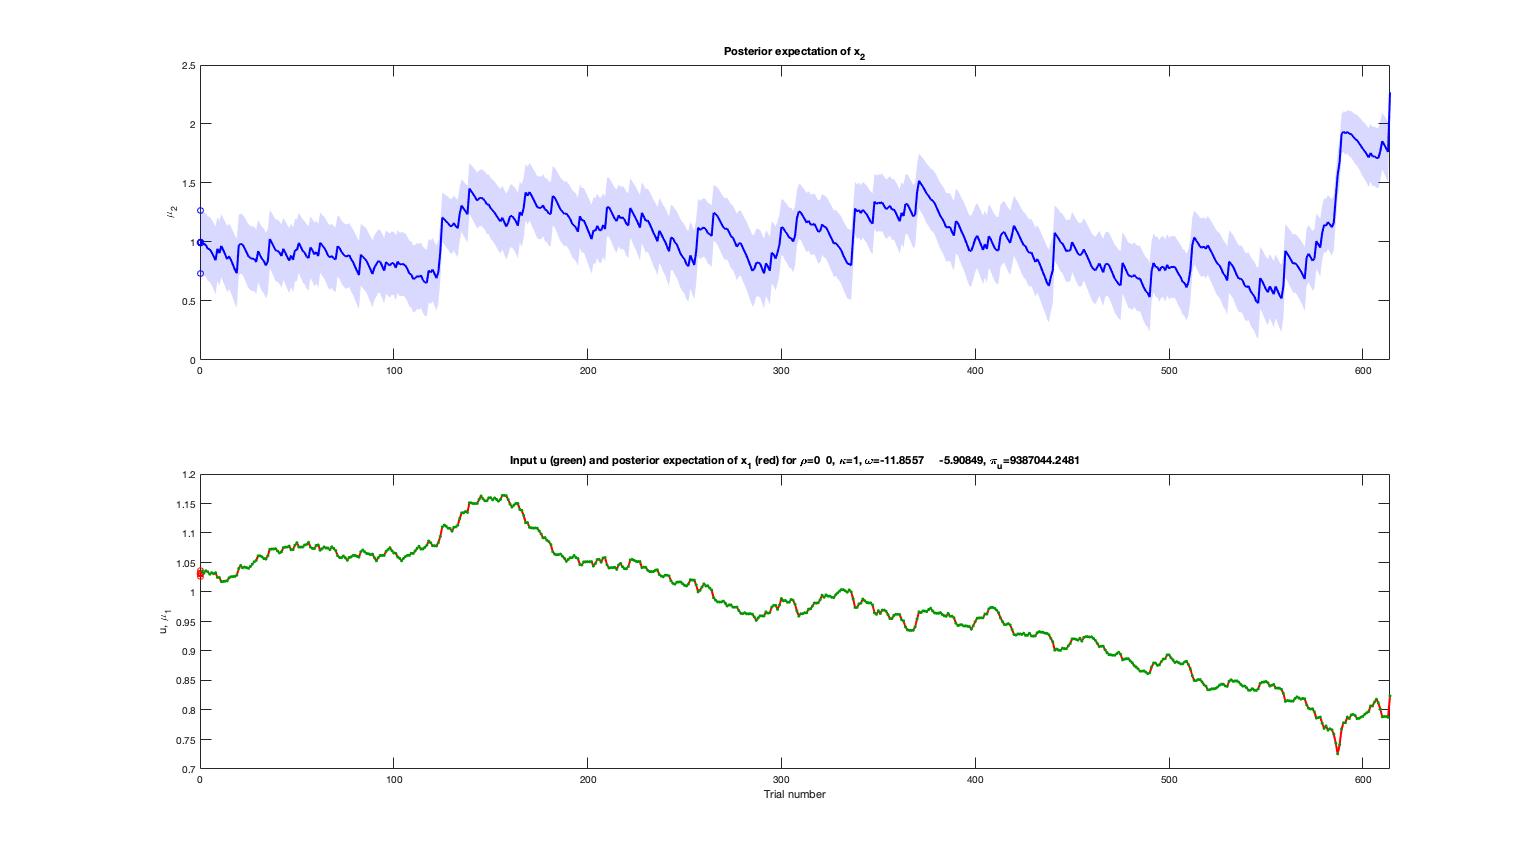

tapas_hgf_plotTraj(bopars2)

Now, let's simulate an agent and plot the resulting trajectories:

sim2 = tapas_simModel(usdchf,...
                      'tapas_hgf',...
                      [1.04 1 0.0001 0.1 0 0 1 -13  -2 1e4],...
                      'tapas_gaussian_obs',...
                      0.00002,...
                      12345);

Ignored trials: none


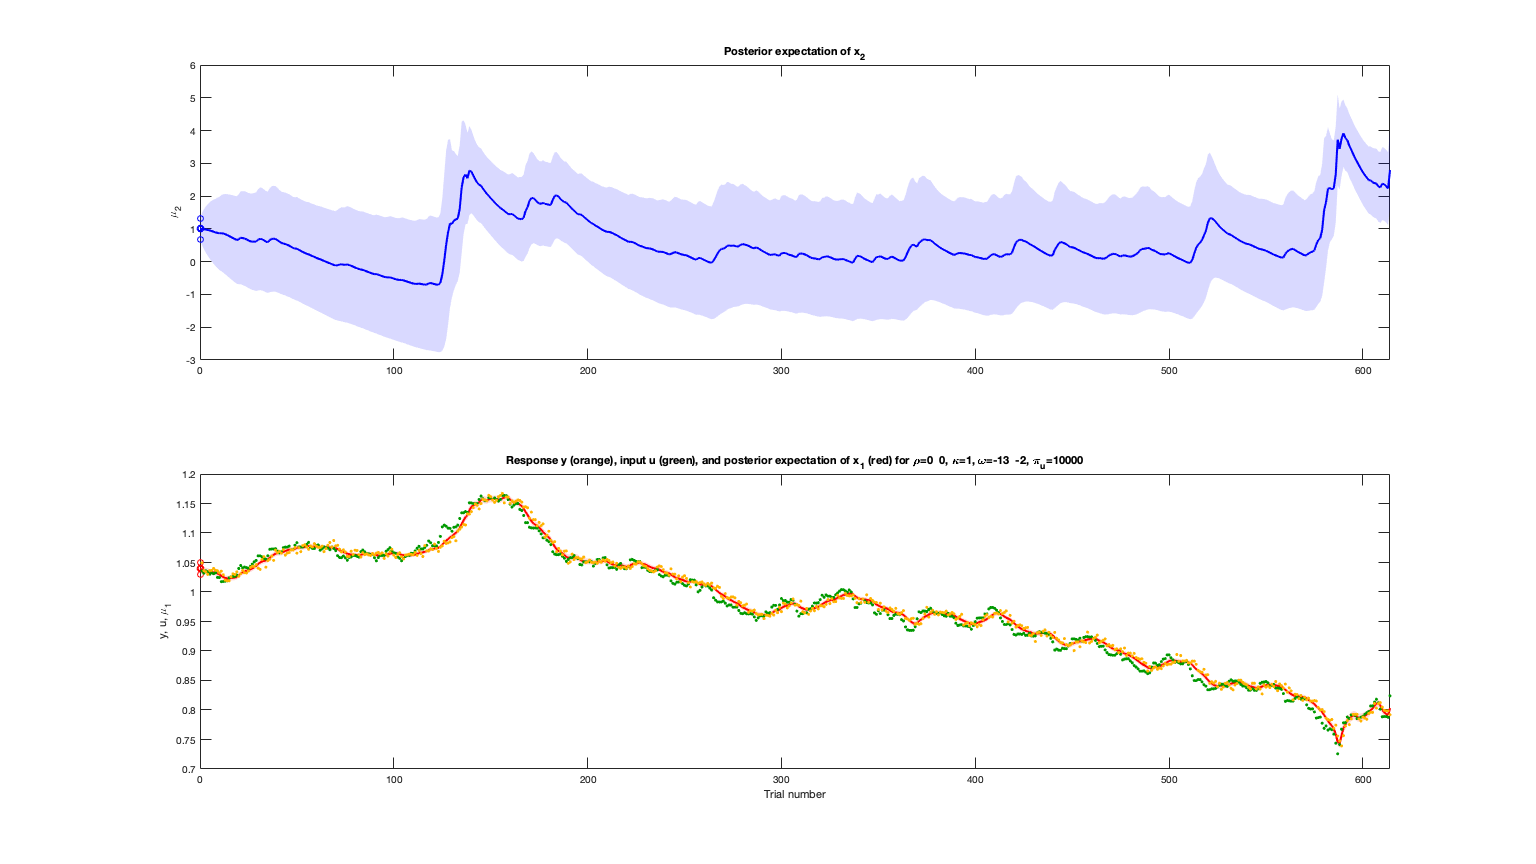

tapas_hgf_plotTraj(sim2)

Looking at the volatility (ie, the second) level, we see that there are two salient events in our time series where volatility shoots up. The first is in April 2010 when the currency markets react to the news that Greece is effectively broke. This leads to a flight into the US dollar (green dots rising very quickly), sending the volatility higher. The second is an accelarating increase in the value of the Swiss Franc in Augutst and September 2011, as the Euro crisis drags on. The point where the Swiss central bank intervened and put a floor under how far the Euro could fall with respect to the Franc is clearly visible in the Franc's valuation against the dollar. This surprising intervention shows up as another spike in volatitlity.

## Adding levels

Let's see what happens if we add another level:

sim2a = tapas_simModel(usdchf,...
                       'tapas_hgf',...
                       [1.04 1 1 0.0001 0.1 0.1 0 0 0 1 1 -13  -2 -2 1e4],...
                       'tapas_gaussian_obs',...
                       0.00005,...
                       12345);

Ignored trials: none


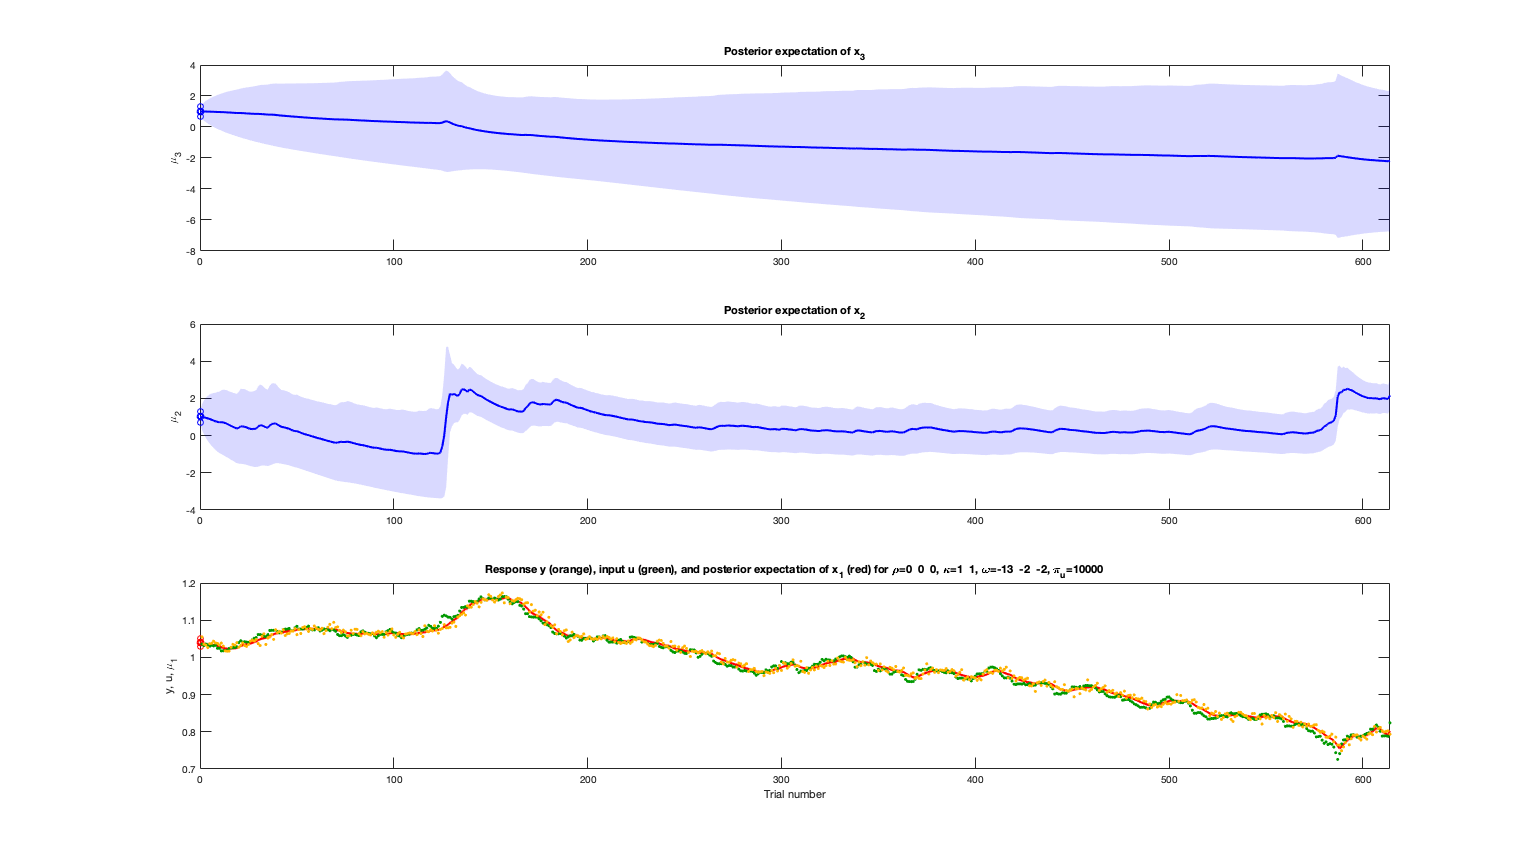

tapas_hgf_plotTraj(sim2a)

Owing to the presence of the third level, the second level is a lot smoother now. At the third level, nothing much happens. This is an indication that adding further levels doesn't make sense. Formally, you can always check whether adding levels is warrented by using the log-model evidence to compare models with different numbers of levels.

## Salient events reflected in precision weights

While the third level is very smooth overall, the two salient events discussed above are still visible. Let's see how these events are reflected in the precision weighting of the updates at each level:

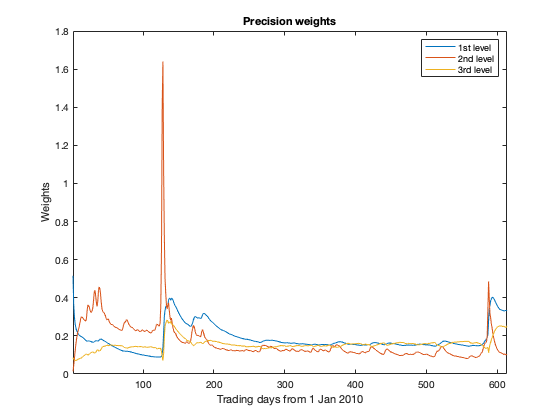

figure
plot(sim2a.traj.wt)
xlim([1, length(sim2a.traj.wt)])
legend('1st level', '2nd level', '3rd level')
xlabel('Trading days from 1 Jan 2010')
ylabel('Weights')
title('Precision weights')

Most prominently at the second level, there is a very clear peak in the precision weights at the moments where the HGF picks up that the environment has changed. This spike in the precision weights leads to an increase in the lerning rate at the corresponding levels, and once the filter has taken the lessons from the new situation on board, the precision weights and with them the learning rates go down again quickly.

## Parameter recovery

Now, let's try to recover the parameters we put into the simulation by fitting the HGF to our simulated responses:

est2 = tapas_fitModel(sim2.y,...
                      usdchf,...
                      'tapas_hgf_config',...
                      'tapas_gaussian_obs_config',...
                      'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [1.0352 1]
    sa_0: [3.7101e-05 0.0996]
     rho: [0 0]
      ka: 1
      om: [-12.8680 -1.8689]
    pi_u: 9.8449e+03

 
Parameter estimates for the observation model:
    ze: 2.3970e-05

Model quality:
    LME (more is better): 2292.6573
    AIC (less is better): -4882.5447
    BIC (less is better): -4851.6048
 
    AIC and BIC are approximations to -2*LME = -4585.3146.
 


Again, we fit the posterior correlation and the estimated trajectories:

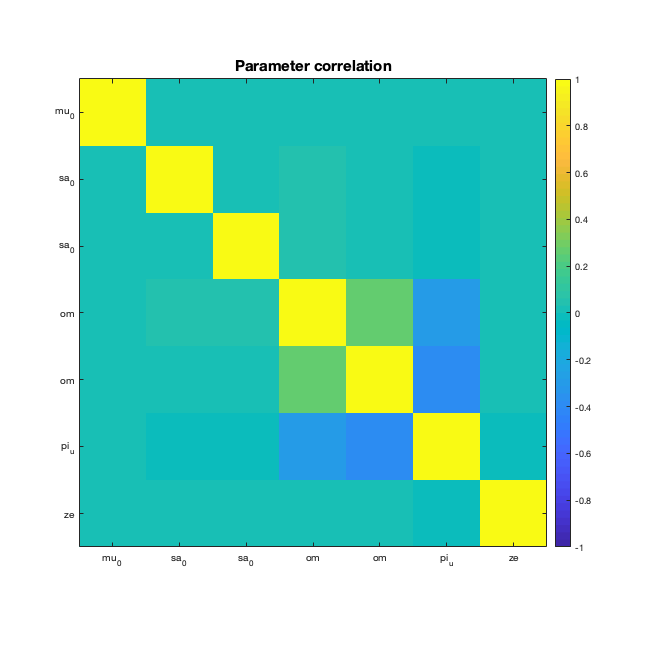

tapas_fit_plotCorr(est2)

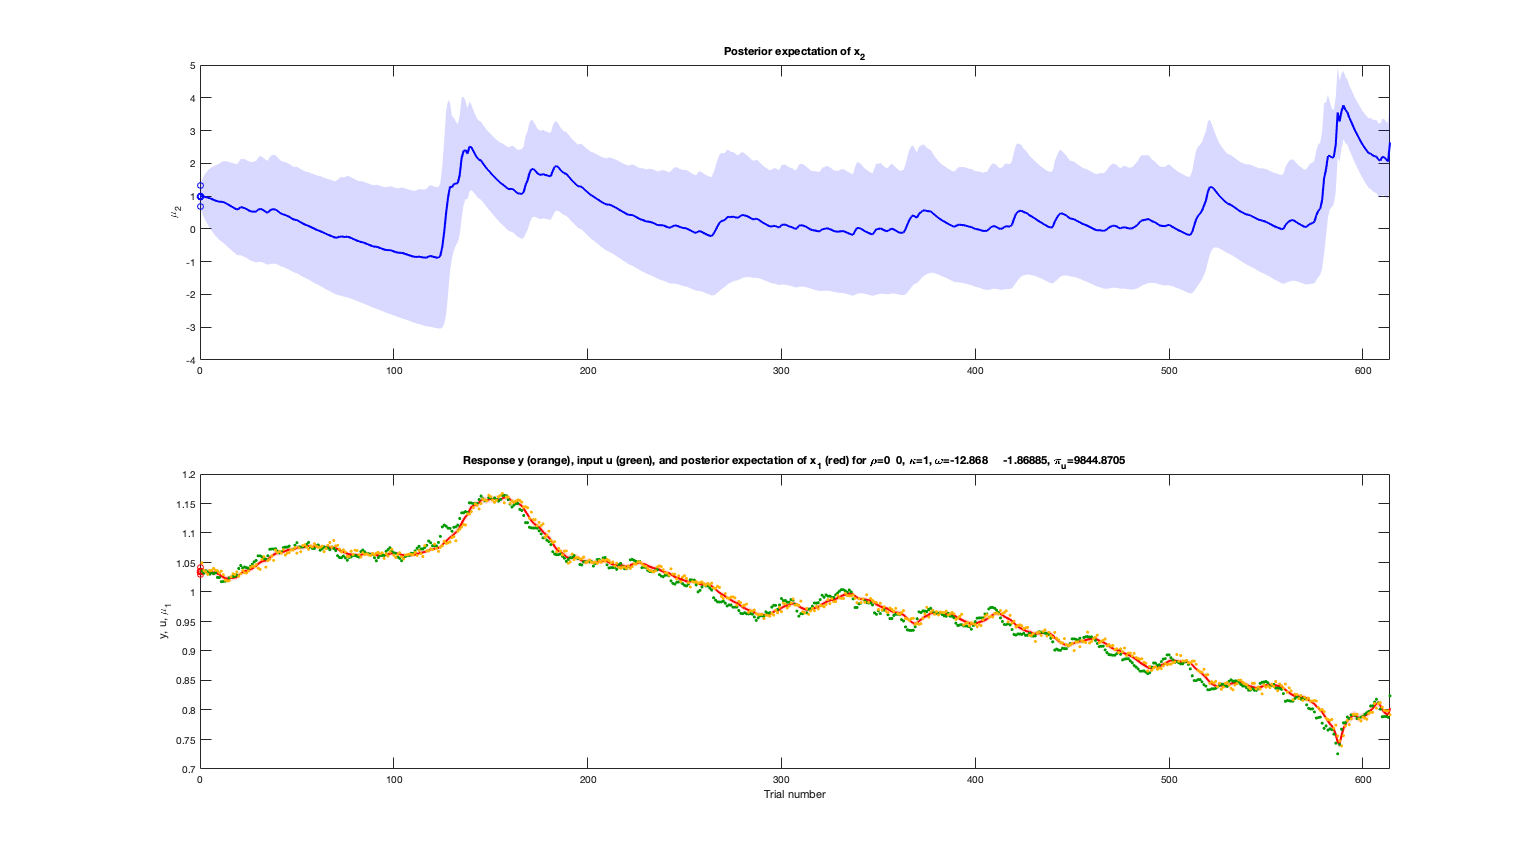

tapas_hgf_plotTraj(est2)

## Plotting residual diagnostics

It's often helpful to look at the residuals (ie, the differences between predicted and actual responses) of a model. If the residual show any obvious patterns, that's an indication that your model fails to capture aspects of the data that should in princple be predictable.

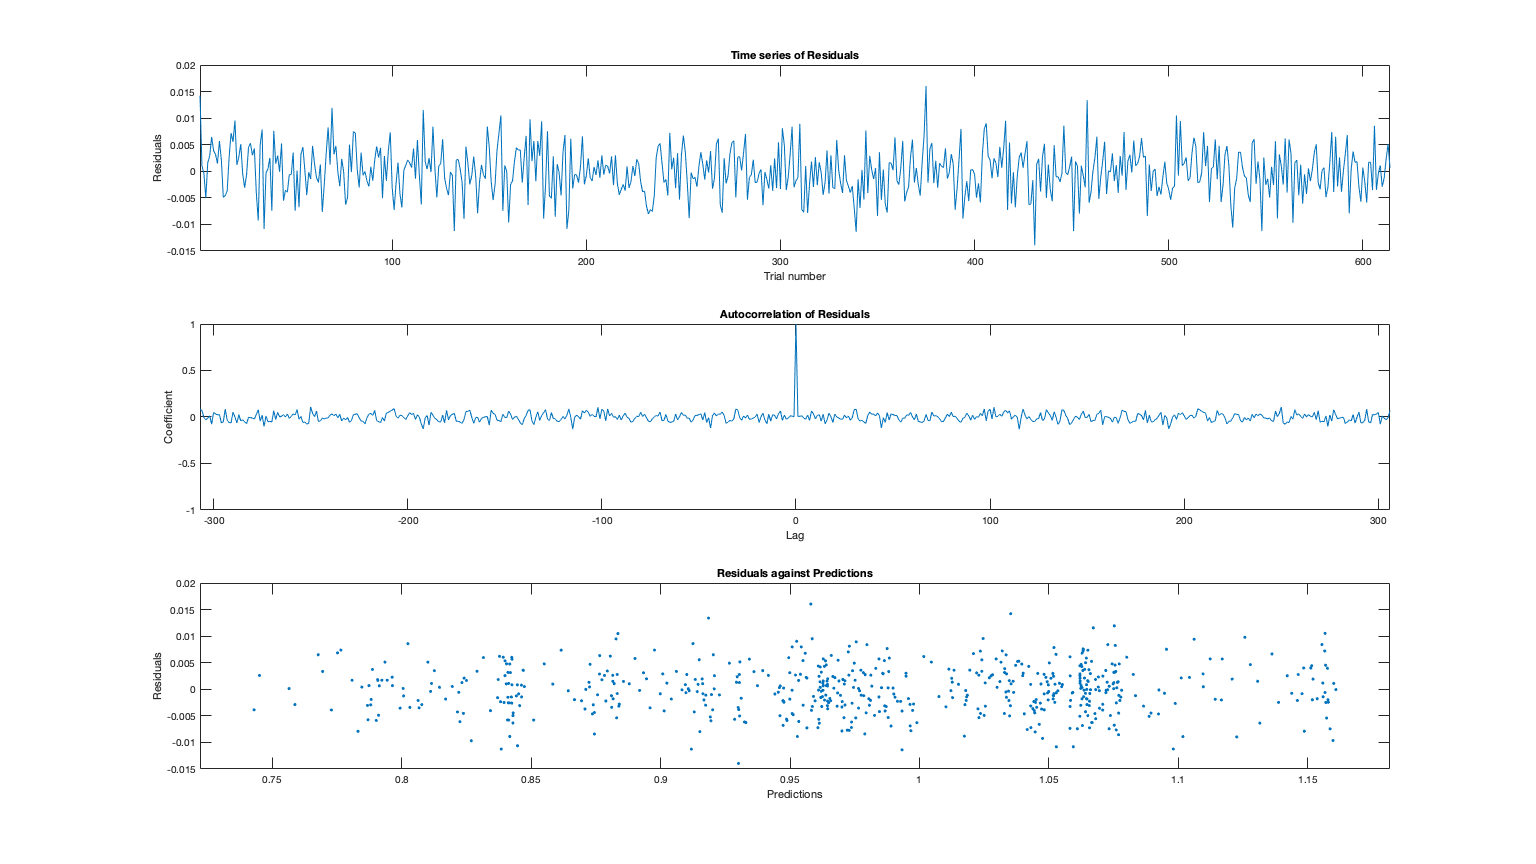

tapas_fit_plotResidualDiagnostics(est2)

Everything looks fine here - no obvious patterns to be seen.

An important point to note is that these are the residuals of the **response model**, not the perceptual model. Ultimately, we want to be able to predict responses, not just filter inputs, and the residuals of the response model capture the performance of the combination of perceptual and response models.

Looking at the same diagnostics for binary responses is less straightforward. The HGF Toolbox uses **Pearson residuals** in this case, defined as


$$r^{(k)} =\frac{y^{(k)} - \hat{\mu}_1^{(k)}}{\sqrt{\hat{\mu}_1^{(k)} \left(1-\hat{\mu}_1^{(k)}\right) }}$$


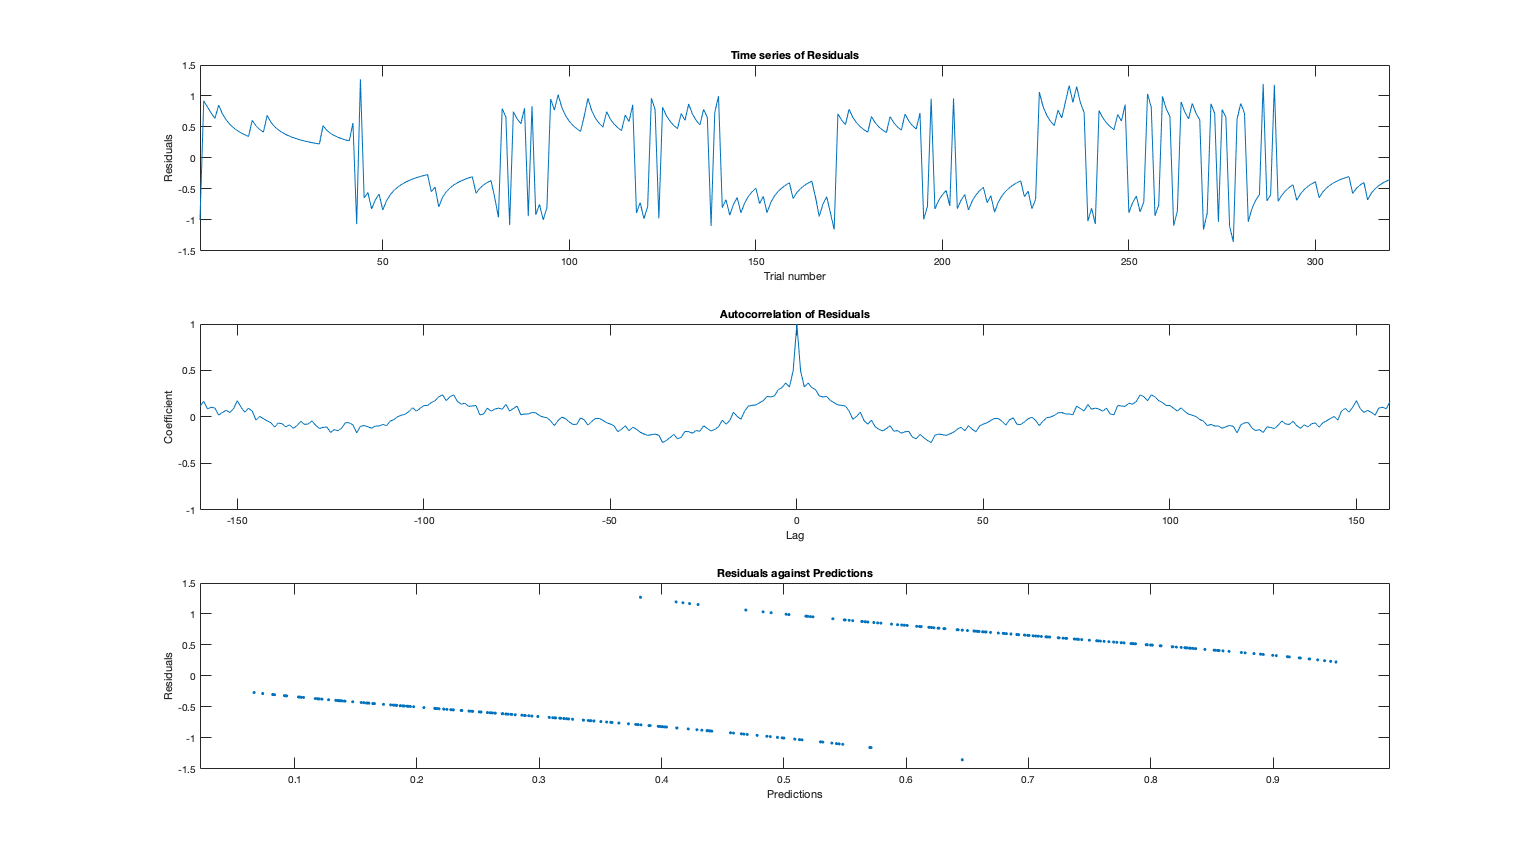

tapas_fit_plotResidualDiagnostics(est)

In the case of our binary response example, we see some patterns in the residuals, notably in their autocorrelation. This is due to the fact that there are fairly regular reversals in the input probabilities. This means that if there are suddenly many large prediction errors following each other, they tend to be in the same direction. At longer lags, we see patterns caused by the regularity of the reversals taking place always after about 45 inputs. Therefore, prediction errors tend to go in the same direction around every 90 inputs.

## Bayesian parameter averaging

It is often useful to average parameters from several estimations, for instance to compare groups of subjects. This can be achieved by using the function *tapas_bayesian_parameter_average()* which takes into account the covariance structure between the parameters and weights individual estimates according to their precision.

We begin by simulating responses from another fictive agent and estimating the parameters behind the simulated responses:

sim2b = tapas_simModel(usdchf,...
                       'tapas_hgf',...
                       [1.04 1 0.0001 0.1 0 0 1 -14.5 -2.5 1e4],...
                       'tapas_gaussian_obs',...
                       0.00002,...
                       12345);

Ignored trials: none


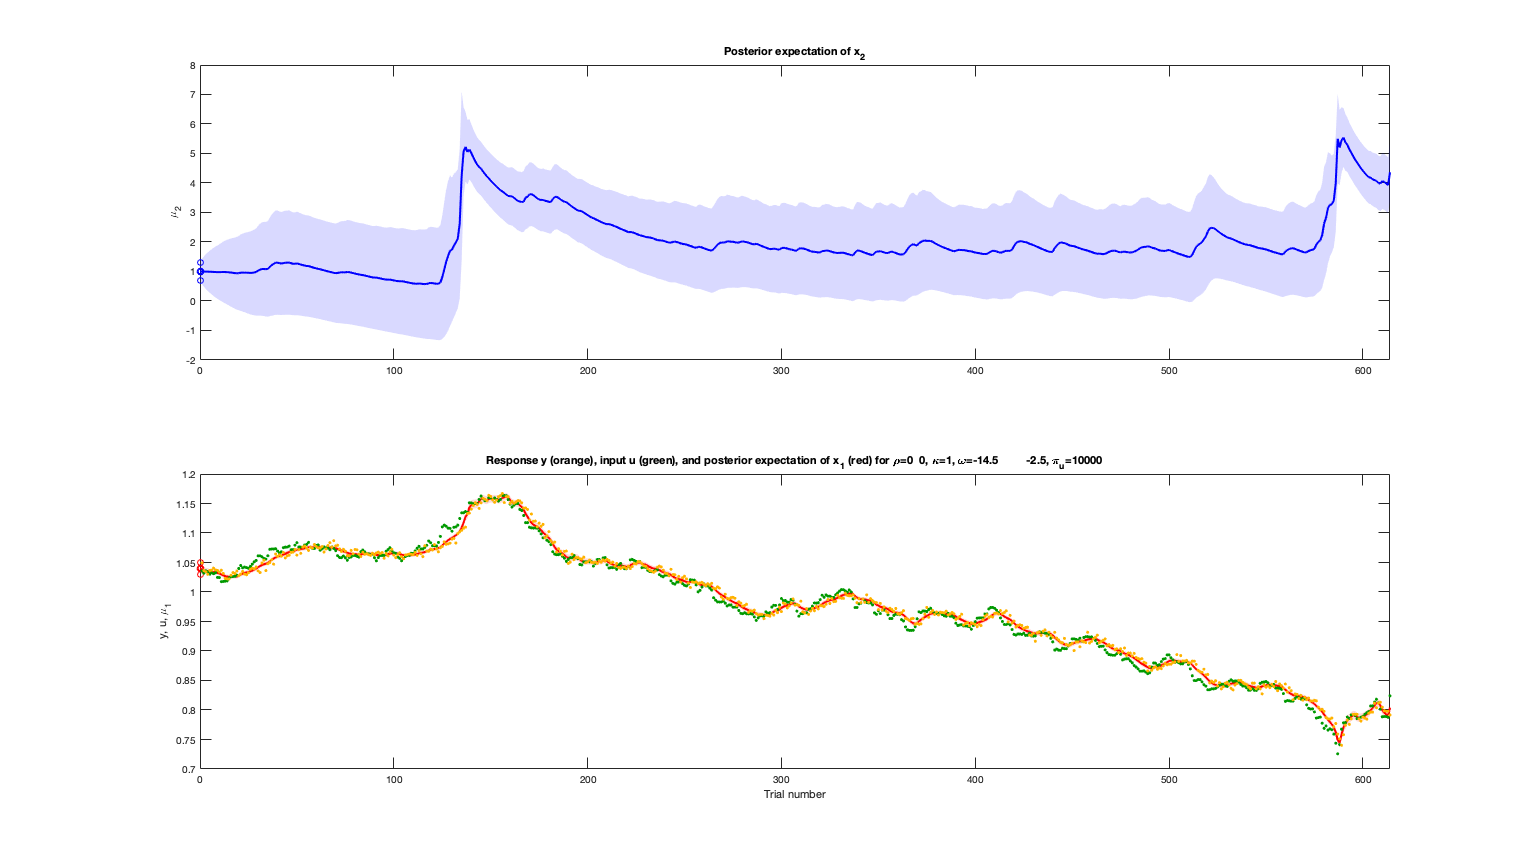

tapas_hgf_plotTraj(sim2b)

est2b = tapas_fitModel(sim2b.y,...
                       usdchf,...
                       'tapas_hgf_config',...
                       'tapas_gaussian_obs_config',...
                       'tapas_quasinewton_optim_config');

Ignored trials: none
Irregular trials: none
 
Optimizing...
 
Calculating the log-model evidence (LME)...
 
Results:
 
Parameter estimates for the perceptual model:
    mu_0: [1.0435 1]
    sa_0: [5.6909e-05 0.0994]
     rho: [0 0]
      ka: 1
      om: [-14.5262 -2.5394]
    pi_u: 1.0049e+04

 
Parameter estimates for the observation model:
    ze: 2.3712e-05

Model quality:
    LME (more is better): 2293.6165
    AIC (less is better): -4889.4861
    BIC (less is better): -4858.5461
 
    AIC and BIC are approximations to -2*LME = -4587.233.
 


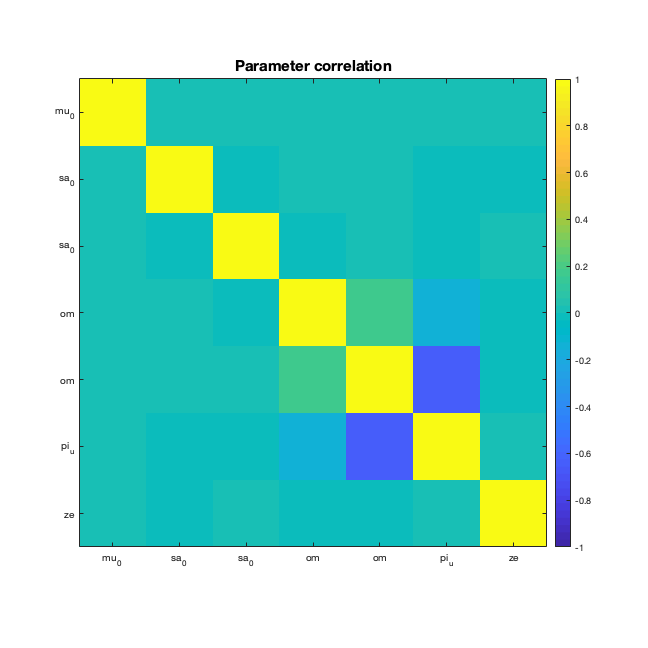

tapas_fit_plotCorr(est2b)

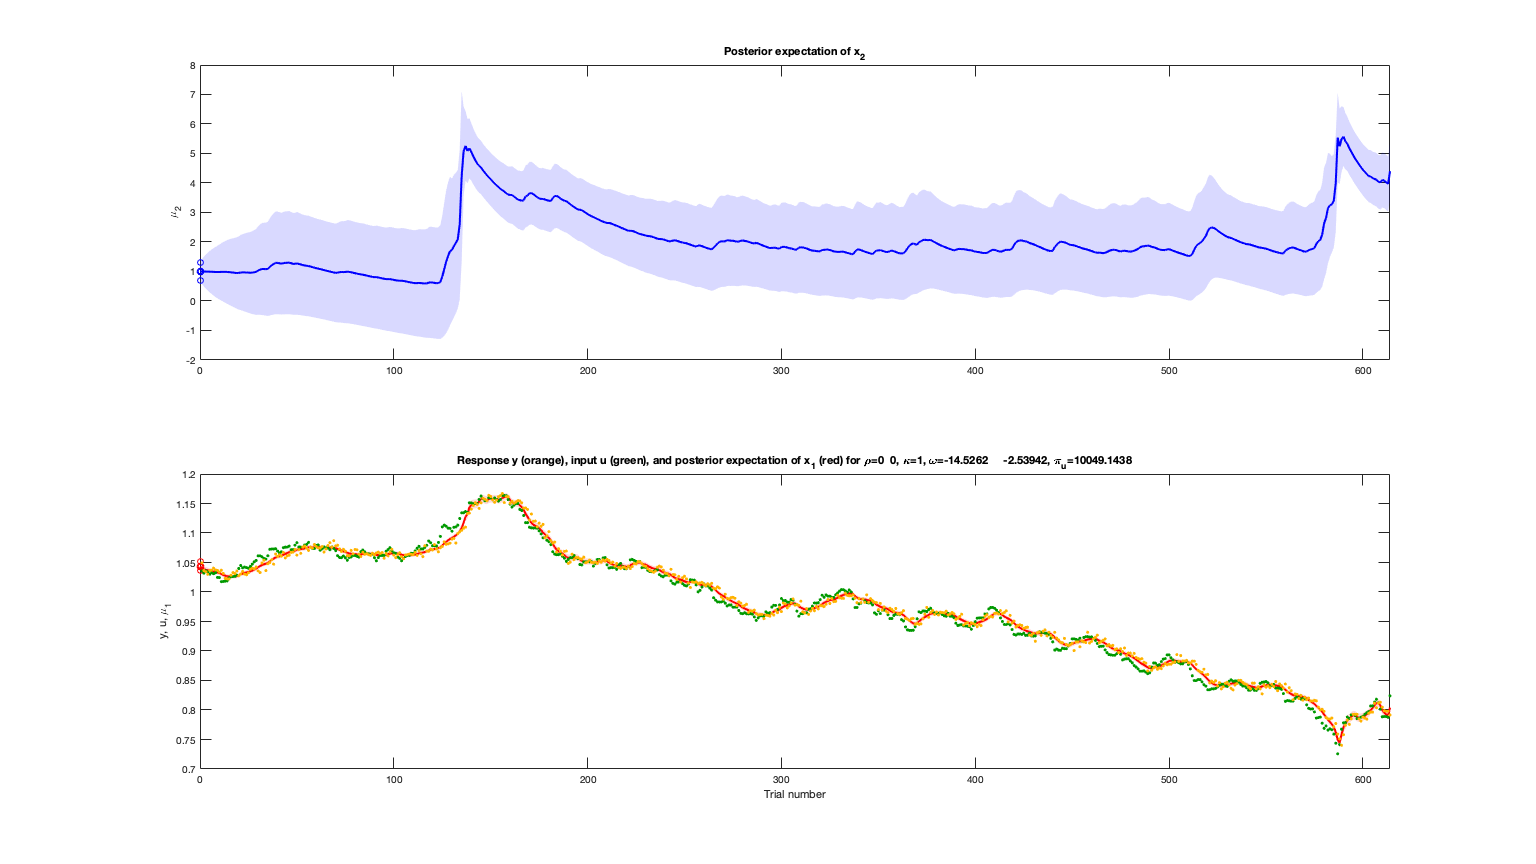

tapas_hgf_plotTraj(est2b)

Now we can take the Bayesian parameter average of our two:

bpa = tapas_bayesian_parameter_average(est2, est2b);

 
Results:
      mu_0: [1.0399 1]
      sa_0: [5.3049e-05 0.0841]
       rho: [0 0]
        ka: 1
        om: [-14.3255 -2.1589]
      pi_u: 9.9432e+03
         p: [1.0399 1 5.3049e-05 0.0841 0 0 1 -14.3255 -2.1589 9.9432e+03]
    ptrans: [1.0399 1 -9.8443 -2.4761 0 0 0 -14.3255 -2.1589 9.2046]

        ze: 2.1475e-05
         p: 2.1475e-05
    ptrans: -10.7486



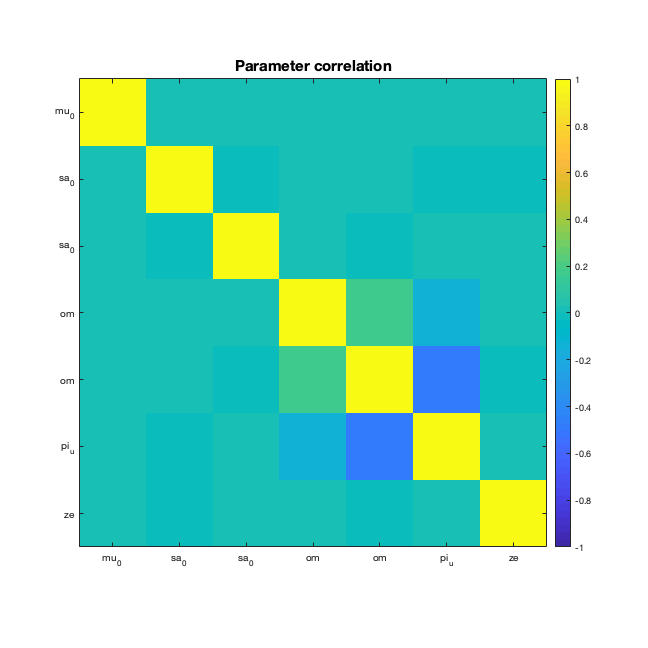

tapas_fit_plotCorr(bpa)

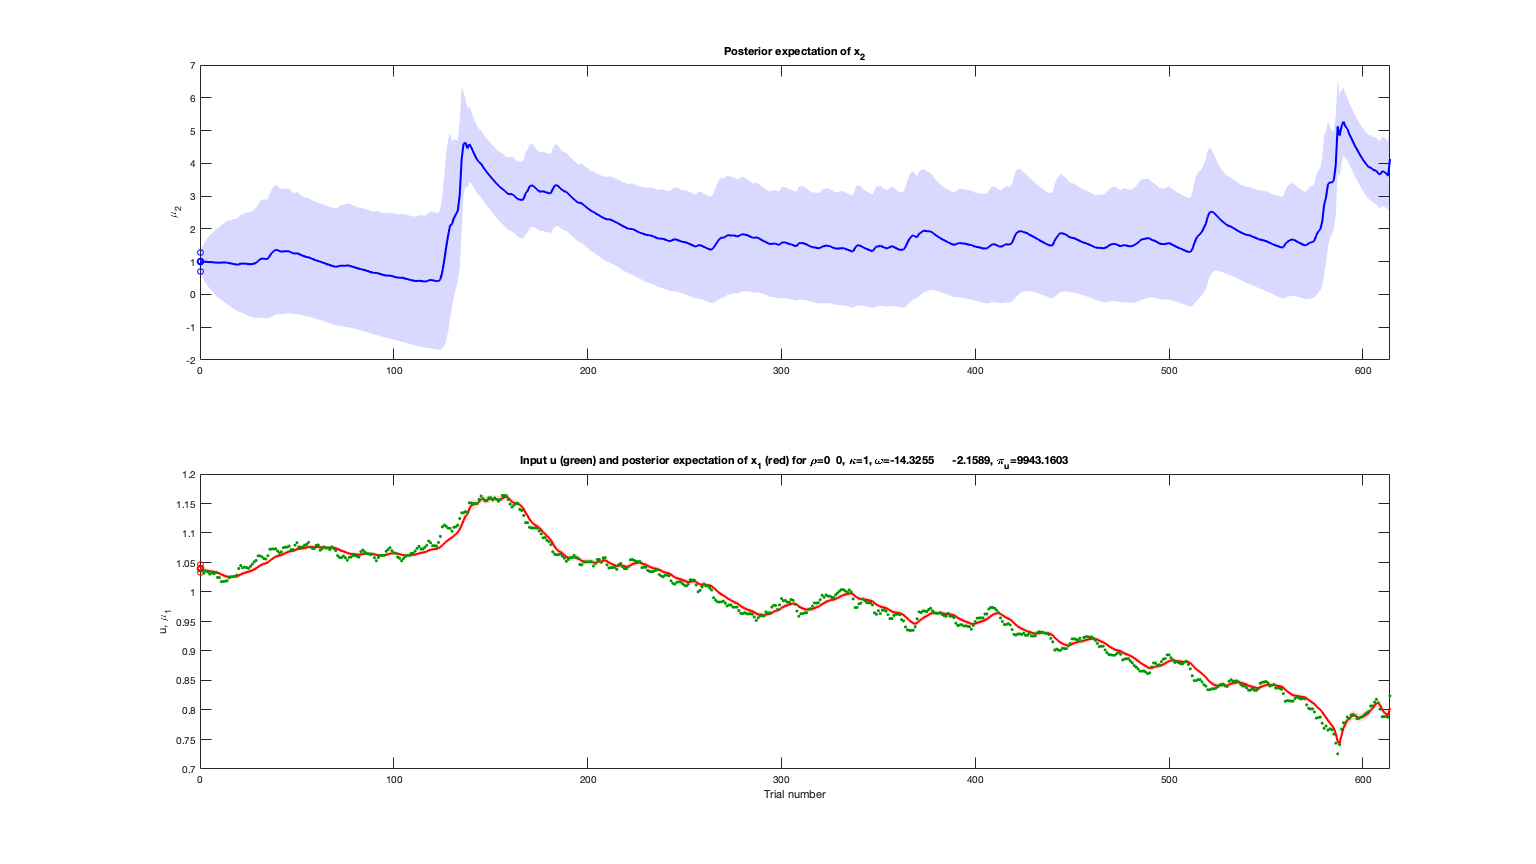

tapas_hgf_plotTraj(bpa)